clear
load carsmall.mat
clear Cylinders Displacement Acceleration Model_Year Model Mfg Origin

a) Document with

1) For d=1, plot:  data, linear regression, afin regression, 

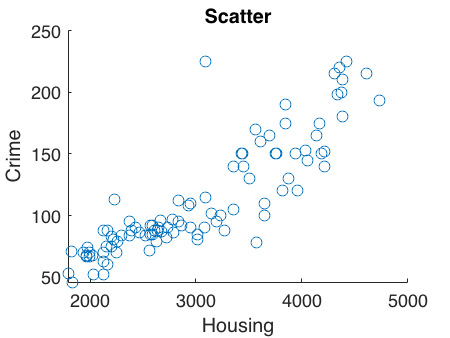

scatter(Weight, Horsepower) % Crime against housing
Horsepower(77)=80;
title('Scatter')
ylabel('Crime')
xlabel('Housing')
hold off

Plot linear regression; we want to predict crime

x_test = Weight(1:20, :);
y_test = Horsepower(1:20, :);
x = Weight(21:end,:); % train
y = Horsepower(21:end, :); % train
b = x/y;
w = x\y; % Slope of the linear regression, weight

Ww should **average **the training and test sets, right now is not representative.

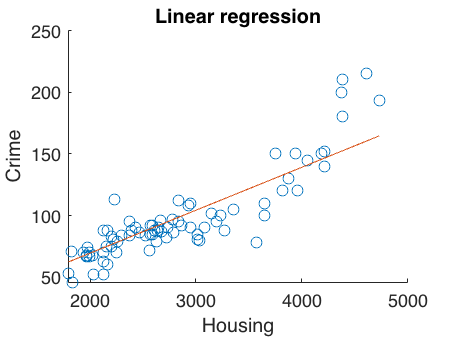

y_lin = w*x;
y_lin_test = w*x_test;
scatter(x, y)
hold on
plot(x, y_lin)
title('Linear regression')
ylabel('Crime')
xlabel('Housing')
hold off

Linear regression should start at 0.

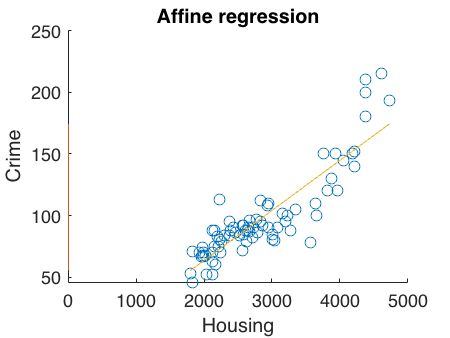

xFine = [ones(length(x), 1), x];
xFine_t = [ones(length(x_test), 1), x_test];
wFine = xFine\y;
y_Fine = xFine * wFine;
y_Fine_t = xFine_t * wFine;
scatter(x, y)
hold on
plot(xFine, y_Fine)
title('Affine regression')
ylabel('Crime')
xlabel('Housing')
hold off

2) For d=1; plot MSEtrain(w) for seeing the minimum value

MSE_lin = 1/length(x)*sum((y_lin-y).^2);
MSE_lin_t = 1/length(x_test)*sum((y_lin_test-y_test).^2); % test
MSE_affine = 1/length(x)*sum((y_Fine-y).^2);
MSE_affine_t = 1/length(x_test)*sum((y_Fine_t-y_test).^2); % test

Difference (Generalization error)

Gen_lin = abs(MSE_lin - MSE_lin_t);
Gen_affine = abs(MSE_affine - MSE_affine_t);

3) For d=1, plot MSE_train(w*) and MSE_test(w*) with hbar function for linear and afin regression

4) plot error with hbar for linear and afin

5) extra: repeat 1,2,3,4 with d=2;

**10th of May**

- **Goal: **Find optimal capaticy for our case

`R(w) = y_pred(wi, xi,)-yi`

Where `y_pred(wi, xi)`; *d=k*, *d* is capacity, *b* is bias

`y_pred = b + sum_1^d wd*xd`

R = zeros(4);
y_pred = zeros(length(x), 1);
for d=1:4
    w(d) = ((x.^d)'*x.^d)\((x.^d)'*y);
    y_pred = y_pred + w(d)*x.^d;
    MSE_d(d) = 1/length(x)*sum((y_pred-y).^2);
end